close all;
clear all; %#ok<CLALL> 
rng('default')

% Load Data Files
load EastCoast.mat
load Supporting_Data_Team_01.mat

### Generating Random Speeds

The problem calls for generating random speeds.  Assume we know the speeds are Normally distributed with a mean of 50 mph and a standard deviation of 5 mph.  We can create a distribution that generates the specific random variable using the command below. **Note, each team will need to determine the speed distributions using the provided data.**

**looks like col 1 is normal or weibull, we can run tests to confirm**

**looks like col 2 is normal or weibull, we can run tests to confirm**

**looks like col 3 is normal or weibull, we can run tests to confirm**

speed_1 = T_speed_data{:,1};
speed_2 = T_speed_data{:,2};
speed_3 = T_speed_data{:,3};
speed_4 = T_speed_data{:,4};

#### Speed_1

Checking if a good dist

pd = fitdist(speed_1,'Normal');
conf = .9;
alpha = 1-conf;
[h,p,st] = chi2gof(speed_1, 'CDF', pd,'Alpha',alpha);
pf = 'FAIL';
if (h == 0) pf = 'Fail to reject';
end
fprintf('chi2 = %6.3f, Test = %s\n',st.chi2stat,pf);

chi2 =  1.764, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,ksstat,cv] = kstest(speed_1,'CDF',pd,'Alpha',alpha);
fprintf('KS Test (MATLAB) statistic = %6.2f, critical value(%d%%) = %6.2f, Test = %s\n', ksstat, conf*100, cv, char(pf(h+1)));

KS Test (MATLAB) statistic =   0.04, critical value(90%) =   0.05, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,adstat,cv] = adtest(speed_1, 'Distribution',pd,'Alpha', alpha);
fprintf('AD Test (MATLAB) statistic = %6.2f, critical value (%d%%) = %6.2f, Test = %s\n', adstat, conf*100, cv, char(pf(h+1)));

AD Test (MATLAB) statistic =   0.32, critical value (90%) =   1.93, Test = Fail to reject


pd_65 = pd;

#### Printing out data vs distribtution

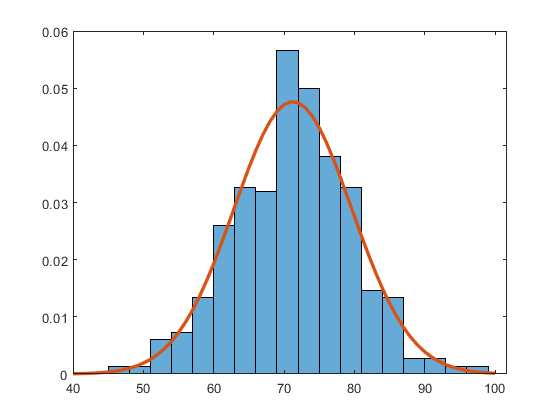

figure(1)
histogram(speed_1,'Normalization',"pdf")
hold on;
x = 40:100;
y = pdf(pd,x);
plot(x,y,'LineWidth',2.5)
hold off;

#### Speed_2

Checking if a good dist

pd = fitdist(speed_2,'Normal');
conf = .9;
alpha = 1-conf;
[h,p,st] = chi2gof(speed_2, 'CDF', pd,'Alpha',alpha);
pf = 'FAIL';
if (h == 0) pf = 'Fail to reject';
end
fprintf('chi2 = %6.3f, Test = %s\n',st.chi2stat,pf);

chi2 =  6.478, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,ksstat,cv] = kstest(speed_2,'CDF',pd,'Alpha',alpha);
fprintf('KS Test (MATLAB) statistic = %6.2f, critical value(%d%%) = %6.2f, Test = %s\n', ksstat, conf*100, cv, char(pf(h+1)));

KS Test (MATLAB) statistic =   0.02, critical value(90%) =   0.05, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,adstat,cv] = adtest(speed_2, 'Distribution',pd,'Alpha', alpha);
fprintf('AD Test (MATLAB) statistic = %6.2f, critical value (%d%%) = %6.2f, Test = %s\n', adstat, conf*100, cv, char(pf(h+1)));

AD Test (MATLAB) statistic =   0.28, critical value (90%) =   1.93, Test = Fail to reject



pd_50 = pd;

#### Printing out data vs distribtution

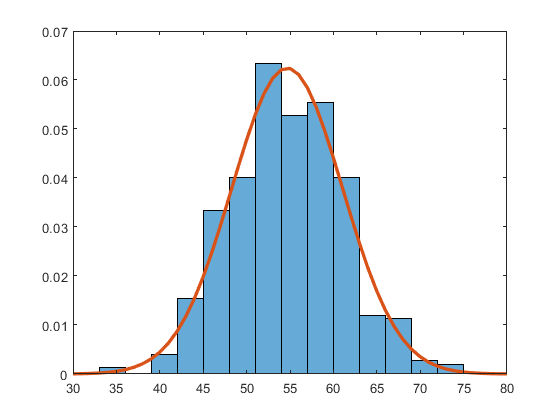

figure(1)
histogram(speed_2,'Normalization',"pdf")
hold on;
x = 30:80;
y = pdf(pd,x);
plot(x,y,'LineWidth',2.5)
hold off;

#### Speed_3

Checking if a good dist

pd = fitdist(speed_3,'Normal');
conf = .9;
alpha = 1-conf;
[h,p,st] = chi2gof(speed_3, 'CDF', pd,'Alpha',alpha);
pf = 'FAIL';
if (h == 0) pf = 'Fail to reject';
end
fprintf('chi2 = %6.3f, Test = %s\n',st.chi2stat,pf);

chi2 =  5.276, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,ksstat,cv] = kstest(speed_3,'CDF',pd,'Alpha',alpha);
fprintf('KS Test (MATLAB) statistic = %6.2f, critical value(%d%%) = %6.2f, Test = %s\n', ksstat, conf*100, cv, char(pf(h+1)));

KS Test (MATLAB) statistic =   0.03, critical value(90%) =   0.05, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,adstat,cv] = adtest(speed_3, 'Distribution',pd,'Alpha', alpha);
fprintf('AD Test (MATLAB) statistic = %6.2f, critical value (%d%%) = %6.2f, Test = %s\n', adstat, conf*100, cv, char(pf(h+1)));

AD Test (MATLAB) statistic =   0.39, critical value (90%) =   1.93, Test = Fail to reject


pd_40 = pd;

#### Printing out data vs distribtution

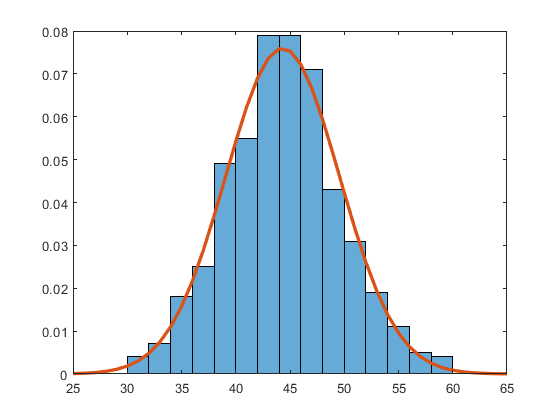

figure(1)
histogram(speed_3,'Normalization',"pdf")
hold on;
x = 25:65;
y = pdf(pd,x);
plot(x,y,'LineWidth',2.5)
hold off;

#### Speed_4

Checking if a good dist

pd = fitdist(speed_4,'Normal');
conf = .9;
alpha = 1-conf;
[h,p,st] = chi2gof(speed_4, 'CDF', pd,'Alpha',alpha);
pf = 'FAIL';
if (h == 0) pf = 'Fail to reject';
end
fprintf('chi2 = %6.3f, Test = %s\n',st.chi2stat,pf);

chi2 =  4.850, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,ksstat,cv] = kstest(speed_4,'CDF',pd,'Alpha',alpha);
fprintf('KS Test (MATLAB) statistic = %6.2f, critical value(%d%%) = %6.2f, Test = %s\n', ksstat, conf*100, cv, char(pf(h+1)));

KS Test (MATLAB) statistic =   0.02, critical value(90%) =   0.05, Test = Fail to reject


pf = {'Fail to reject', 'Reject'};
[h,p,adstat,cv] = adtest(speed_4, 'Distribution',pd,'Alpha', alpha);
fprintf('AD Test (MATLAB) statistic = %6.2f, critical value (%d%%) = %6.2f, Test = %s\n', adstat, conf*100, cv, char(pf(h+1)));

AD Test (MATLAB) statistic =   0.32, critical value (90%) =   1.93, Test = Fail to reject


pd_15 = pd;

#### Road Condition Distribution

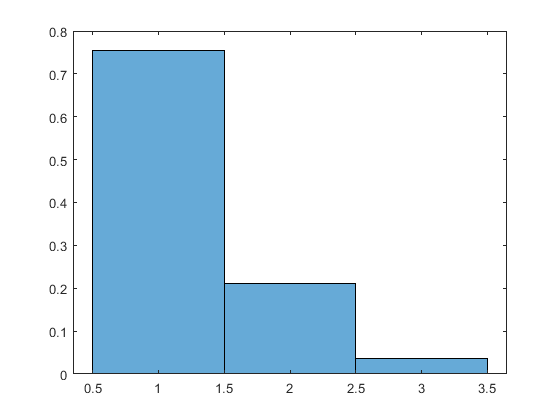

A_roadcond_data = table2array(T_roadcond_data);

for x = 1:length(A_roadcond_data)
    if A_roadcond_data(x) == "Normal"
        roadcond_int_data(x) = 1;
    elseif A_roadcond_data(x) == "Construction"
        roadcond_int_data(x) = 2;
    elseif A_roadcond_data(x) == "Accident"
        roadcond_int_data(x) = 3;
    else
        error('Error: somethings wrong');
    end
end

onesum = sum(roadcond_int_data==1);
twosum = sum(roadcond_int_data==2);
threesum = sum(roadcond_int_data==3);
road_cond_p = [onesum/length(roadcond_int_data) twosum/length(roadcond_int_data) threesum/length(roadcond_int_data)];
road_cond_cdf = [road_cond_p(1) road_cond_p(1)+road_cond_p(2) road_cond_p(1)+road_cond_p(2)+road_cond_p(3)];
z0 = [1 2 3];
N = 15959;

y = rand([N 1]);
z = zeros(N,1);
for i=1:N
      indx = find( road_cond_cdf >= y(i), 1, 'first');
      z(i) = z0(indx);
end
figure(1)
histogram(z,'Normalization',"pdf");

Gen New File

for iter = 1:size(G.Edges)
    speed_data_out = table2array(G.Edges(iter,"Speed"));
    distance_data_out = table2array(G.Edges(iter,"Distance"));
    if z(iter) == 1
        if speed_data_out == 65
            out_speed = random(pd_65,1);
            G.Edges(iter,"Speed") = array2table(out_speed);
            G.Edges(iter,"Weight") = array2table(1/out_speed * distance_data_out);
        elseif speed_data_out == 50
            out_speed = random(pd_50,1);
            G.Edges(iter,"Speed") = array2table(out_speed);
            G.Edges(iter,"Weight") = array2table(1/out_speed * distance_data_out);
        end
    elseif z(iter) == 2
            out_speed = random(pd_40,1);
            G.Edges(iter,"Speed") = array2table(out_speed);
            G.Edges(iter,"Weight") = array2table(1/out_speed * distance_data_out);
    elseif z(iter) == 3
            out_speed = random(pd_15,1);
            G.Edges(iter,"Speed") = array2table(out_speed);
            G.Edges(iter,"Weight") = array2table(1/out_speed * distance_data_out);
    end
end

H = G;
save("EastCoast_w_supporting_data.mat","H");

#### Printing out data vs distribtution

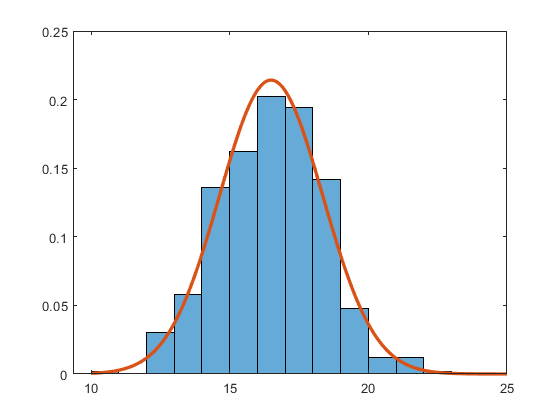

figure(1)
histogram(speed_4,'Normalization',"pdf")
hold on;
x = 10:.1:25;
y = pdf(pd,x);
plot(x,y,'LineWidth',2.5)
hold off;